# **MSc Translation Neuroscience Module 3 - Workshop 1**

# **Machine Learning**

# 1. Principal Component Analysis (PCA)

### 1.1 The theory

Principal Component Analysis or PCA is a dimension reduction technique, and is one of the most basic machine learning algorithms.

The idea is to project N-dimensional data into a new p-dimensional (orthogonal) coordinate system, such that the new coordinate system maximises the variance across the data.

A visual representation of this from a 3-D dataspace to a 2-D space can be seen below (adapted from [here](https://towardsdatascience.com/principal-component-analysis-pca-explained-visually-with-zero-math-1cbf392b9e7d)):

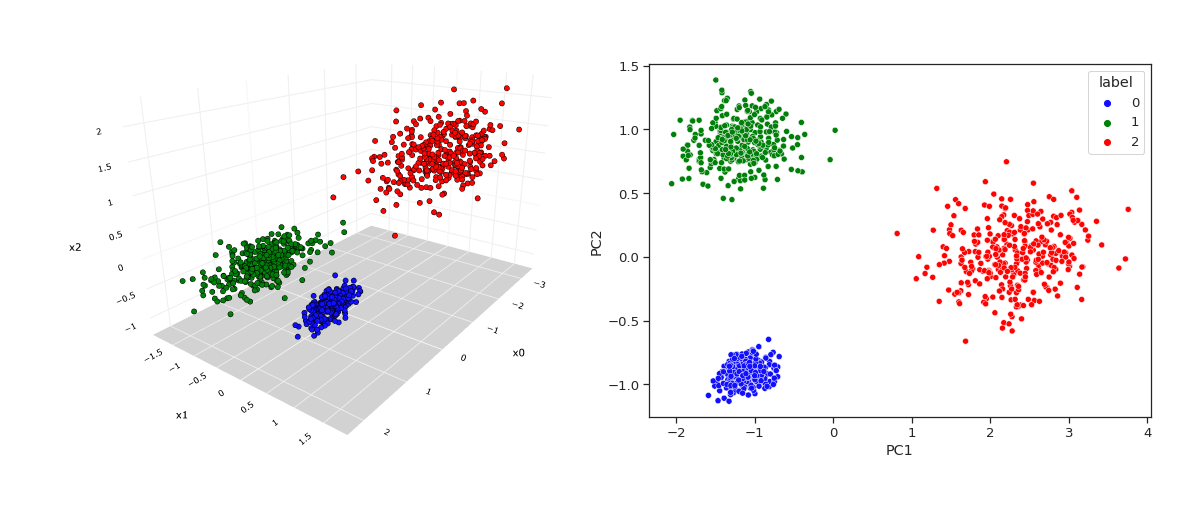

In this case, we have gone from three dimensions to two dimensions, with minimal information loss. 

If you are interested in the maths behind it, this involves eigendecomposition, and projecting your data matrix into your eigenvectors. If this doesn't make any sense to you, don't worry! If you want to learn more about it, you can read the[ wikipedia page](https://en.wikipedia.org/wiki/Principal_component_analysis#:~:text=Principal%20component%20analysis%20(PCA)%20is,analysis%2C%20visualization%20and%20data%20preprocessing.) on it: 

The reason why this is a machine learning algorithm, is because the projection axes are fully dependent on the data itself, meaning the projection weights are **learned** from the **data**.

### 1.2 Use cases

PCA is an extremely useful and widely used method of dimensionality reduction. Imagine you have patient data such as Age, Disease duration, Disease severity, Acceleration power, and Tremor score for a series of patients. Whilst these features are all different, they are not independent from one another. For example, the tremor score and acceleration power would be highly correlated. Same for the Disease duration and Disease severity. By using PCA, we could go from a 6-D feature space to a 2-D feature space, with minimal information loss. This decrease in dimensionality makes our dataset more easy to visualise, and makes it easier to handle with machine learning algorithms.

### 1.3 Implementing PCA

Let's try PCA now!

**1.3.1 Loading the data**

Let's start by loading the UPDRS data (motor impairment scores) from the PPMI dataset:

updrs = readtable("Data\UPDRS_part3.csv")

updrs = 29461×39 table
    PATNO    EVENT_ID     INFODT     NHY     PDSTATE      NP3SPCH    NP3FACXP    NP3RIGN    NP3RIGRU    NP3RIGLU    NP3RIGRL    NP3RIGLL    NP3FTAPR    NP3FTAPL    NP3HMOVR    NP3HMOVL    NP3PRSPR    NP3PRSPL    NP3TTAPR    NP3TTAPL    NP3LGAGR    NP3LGAGL    NP3RISNG    NP3GAIT    NP3FRZGT    NP3PSTBL    NP3POSTR    NP3BRADY    NP3PTRMR    NP3PTRML    NP3KTRMR    NP3KTRML    NP3RTARU    NP3RTALU

The columns starting with NP3 show the results from different UPDRS assignments. These assignments take into account things such as rigidity or tremor of different parts of the body. It is therefore likely that there is some redundancy in these, and we could use PCA to have a compact representation of our data!

**1.3.2 Applying PCA in MATLAB**

If you read the documentation of the `pca()` function, you will see that it is expecting the data as an `n x p `matrix, where `n` is the number of samples and `p `is the number of features.

Let's extract that!

*Exercise 1.1*

Extract the data from the table to have the desired dimensions. Don't include the last column (total score). You should have 33 columns in total

*Hint: Use the *`table2array()`* function to transform the sub-table to a matrix*

data = updrs(:,6:end-1);
data = table2array(data);

Let's remove invalid rows:

data = data(~any(isnan(data),2),:);

Now let's put that into PCA:

[projection_vectors, data_pca, variance_raw, ~, variance_explained] = pca(data);

As you can see, pca has many outputs. We will look at the important ones below, but for more info you can read MATLAB's documentation of the function.

% Data projected into the new axis:
disp(data_pca)

  -34.1785   -0.7199    0.9563    0.4086    1.1317   -0.1649    0.6315    0.3017    0.2272    0.3808   -0.1062    0.5617   -0.3195   -0.5590   -0.7330    0.6754   -0.2208   -0.2455   -0.6209   -0.4631    0.0778   -0.3618   -0.3698    0.1487   -0.0981    0.1730   -0.3097   -0.1344   -0.4997   -0.0046   -0.0227    0.1469   -0.0159
  -34.2727   -1.4217    0.3596    0.7026    1.5227   -0.3311    0.7915    0.1121    0.1982    0.4324   -0.0342    0.5034   -0.2297   -0.6487   -0.5024    0.0433   -0.2482    0.0361    0.0921   -0.0793    0.2249   -0.2985    0.0965    0.0933    0.0020    0.0941   -0.3172   -0.1318    0.0393   -0.1325    0.0440   -0.0065   -0.0188
  -34.2527   -1.2095    0.0173    0.5392    0.7917   -0.1119    0.1921    0.5081   -0.1447    0.0931    0.1478    0.5854    0.0601   -0.7406   -0.5420   -0.0957   -0.0997   -0.4387    0.2329   -0.9800    0.2294   -0.3128   -0.3437    0.1393   -0.1211    0.2378   -0.3519   -0.1150    0.0447   -0.0735   -0.0595   -0.0072   -0.0286
  -34.2


% Principal Component Coefficients (Loadings):
% The projection to the new axis is defined by X_pca = X*W
% where W is the projection_vectors matrix and X is the data matrix
disp(projection_vectors); % Each column is a projection vector

    0.0004    0.0129   -0.0190   -0.0085   -0.0332    0.0113   -0.0335    0.0087   -0.0128   -0.0052   -0.0090    0.0181    0.0303    0.0299    0.0040   -0.0041   -0.0293    0.0205   -0.0063    0.0329   -0.0233    0.0583    0.0119    0.0147   -0.0527    0.0257    0.9894    0.0690    0.0265   -0.0003    0.0053   -0.0026   -0.0018
    0.0031    0.0509   -0.0865   -0.0367   -0.1456    0.0394   -0.1005    0.0335   -0.0485   -0.0233   -0.0140   -0.0275    0.0247    0.0408    0.0768   -0.0464   -0.0385    0.1359   -0.0646    0.3242   -0.0954    0.8371   -0.2848    0.0461    0.0962    0.0042   -0.0767    0.0459    0.0073   -0.0074   -0.0267   -0.0016   -0.0033
    0.4077   -0.0542   -0.0080   -0.0583   -0.0313   -0.1616   -0.0056   -0.0037   -0.0086    0.0016    0.0057   -0.0056   -0.0034   -0.0157    0.0386    0.0056    0.0242    0.0152    0.0650    0.0118   -0.4946   -0.0395    0.1297    0.6868   -0.1572    0.1419   -0.0311   -0.0094    0.0011   -0.1113    0.0114   -0.0024    0.0078
    0.4

%Variance Explained by Each Principal Component (%):
for i=1:length(variance_explained)
    disp("Component: "+i+": "+round(variance_explained(i),2)+"%")
end

Component: 1: 80.9%
Component: 2: 9.4%
Component: 3: 2.16%
Component: 4: 1.25%
Component: 5: 1.13%
Component: 6: 1.01%
Component: 7: 0.72%
Component: 8: 0.51%
Component: 9: 0.43%
Component: 10: 0.38%
Component: 11: 0.26%
Component: 12: 0.24%
Component: 13: 0.2%
Component: 14: 0.18%
Component: 15: 0.17%
Component: 16: 0.15%
Component: 17: 0.14%
Component: 18: 0.12%
Component: 19: 0.1%
Component: 20: 0.08%
Component: 21: 0.07%
Component: 22: 0.07%
Component: 23: 0.06%
Component: 24: 0.05%
Component: 25: 0.04%
Component: 26: 0.04%
Component: 27: 0.03%
Component: 28: 0.03%
Component: 29: 0.02%
Component: 30: 0.02%
Component: 31: 0.02%
Component: 32: 0.02%
Component: 33: 0.01%


This shows us that over 90% of the variance in the data is explained by just the first two components, and around 98% by the first 10. This tells us that there is a lot of redundancy in our data, and allows us to have very compact representation of it, with only minimal information loss.

We can also plot the importance of each principal component to have a visual intuition of which components to pick:

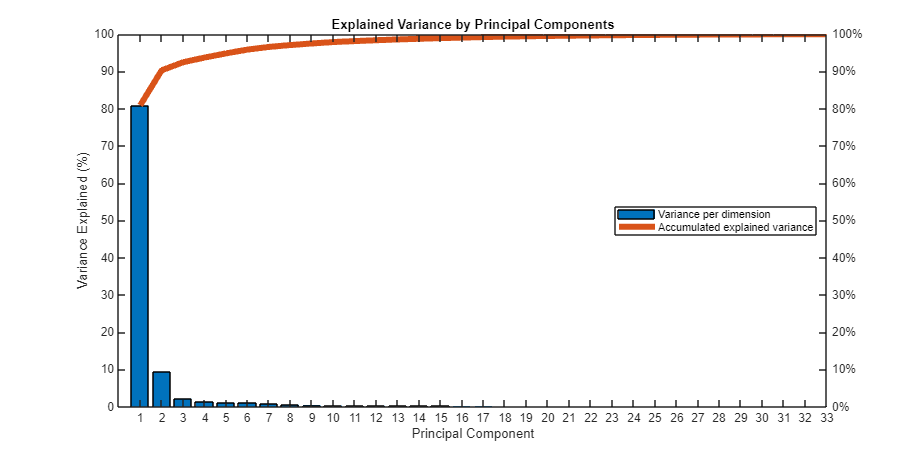

figure('Position',[600,100,1200,600]);
[charts, ax] = pareto(variance_explained); % pareto function does the plotting
xlim([0,33]) % Set xlimit to see all components
xticks(1:33) % Label all components
xticklabels([1:33])
xtickangle(0)
charts(2).LineWidth = 5;
xlabel('Principal Component');
ylabel('Variance Explained (%)');
title('Explained Variance by Principal Components');
lgd = legend("Variance per dimension", "Accumulated explained variance");
lgd.Location = 'east';

Here we can get a good feel for the variance explained, and we see again that most of it is explained by the first two principal components, and that  probably taking PCs after 10 will not bring much information.

Since we can explain most of our data with only 2 PCs, we can now plot our individual samples and try to look for patterns!

*Exercise 1.2*

Plot the data from the first 2 PCs. To do so, you need to use data_pca, and define one of them as the x of your plot and the other component as the y of your plot, make sure to label your axes and give your plot a relevant title.

Then, make a comment on what you see.

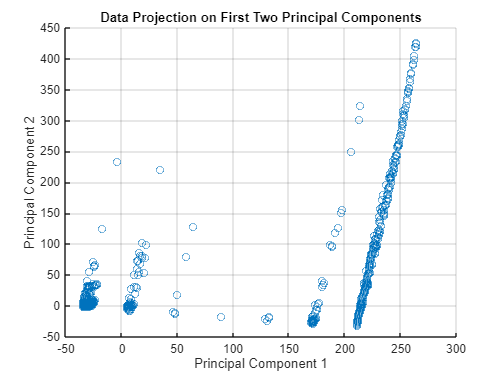

figure;
scatter(data_pca(:,1), data_pca(:,2));
xlabel('Principal Component 1');
ylabel('Principal Component 2');
title('Data Projection on First Two Principal Components');
grid on;

Well done! You might have seen that the data seems to follow different lines that are very clearly separated, this means we see clustering in our data. This is one of PCAs great strengths, which is that if before we had clustering in 33-D space, we can now separate our data points into classes using only 2 dimensions. In the case of medical data, these differences often come from differences in disease characteristics or in demographics.

Finally, using a bar chart, we can see how much each initial feature contributed to the first two components. This can be very useful to know if some features are less useful than others and to get an idea of how different the two first PCs are in terms of our initial feature space:

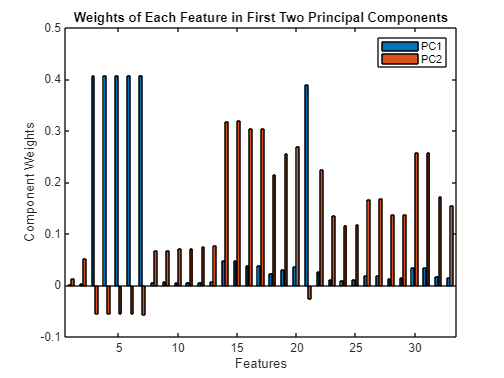


figure;
bar(projection_vectors(:,1:2));  % Plot the weights for the first two components
xlabel('Features');
ylabel('Component Weights');
legend('PC1', 'PC2');
title('Weights of Each Feature in First Two Principal Components');

*Exercise 1.3*

Analyse the graph above and describe patterns you see between the two principal components. Are some features more important than others? How similar are the two first principal components?

PCA is a linear process, meaning it is fully reversible. This makes it a great way to reconstruct original data whilst removing noise.

We saw before that `X_pca = X*W.`

This equation allows us to fully reconstruct our original data: `X = X_pca*V'.` (This is not a straightforward derivation, and has to do with the properties of the matrix W, you can look up the mathematical derivation if you are interested).

This gives us a great use case for denoising data, where the last PCs might not contain relevant information, so by removing them from `X_pca `and `V, `we are able to generate a reconstructed version of our data.

For example with `p` components, we can write it in matlab as:

p = 2

p = 2

data_reconstructed = data_pca(:,1:p) * projection_vectors(:,1:p)'

data_reconstructed =    -0.0243   -0.1434  -13.8942  -13.8884  -13.9040  -13.9133  -13.9139   -0.2535   -0.2767   -0.2300   -0.2533   -0.2627   -0.3055   -1.8401   -1.8734   -1.5364   -1.5464   -0.9555   -1.2237   -1.4153  -13.3300   -1.0791   -0.4818   -0.4056   -0.4296   -0.7613   -0.7872   -0.5454   -0.5816   -1.3300   -1.3412   -0.7287   -0.6152
   -0.0334   -0.1794  -13.8946  -13.8887  -13.9045  -13.9133  -13.9129   -0.3009   -0.3250   -0.2803   -0.3036   -0.3161   -0.3605   -2.0681   -2.1021   -1.7533   -1.7641   -1.1084   -1.4062   -1.6083  -13.3484   -1.2387   -0.5783   -0.4884   -0.5136   -0.8803   -0.9076   -0.6424   -0.6795   -1.5141   -1.5255   -0.8513   -0.7257
   -0.0307   -0.1685  -13.8979  -13.8921  -13.9078  -13.9168  -13.9167   -0.2866   -0.3104   -0.2651   -0.2884   -0.3000   -0.3439   -1.9996   -2.0333   -1.6880   -1.6986   -1.0624   -1.3513   -1.5503  -13.3462   -1.1907   -0.5492   -0.4634   -0.4883   -0.8445   -0.8714   -0.6132   -0.6500   -1.4587   -1.4701   -0.8

# 2. Classification

So, we have seen that machine learning can be used to get efficient and meaningful representations of high-dimensional data. This is great as a preprocessing method, so now let's look at how AI can be used to draw conclusions from our input data. In most cases, this is done through classificaiton.

### 2.1 What is Classification

Classification is the process of giving labels to input samples. For example, if you have a dataset of pet images, a machine learning algorithm (or model) would classify the images into dogs and cats, assigning to each image one of the two labels. 

An example of this in medical data, is if you have a dataset of brain MRIs and your model needs to give it a label of "Healthy Control" or "Parkinson's Disease", this would be a binary classification task, where binary indicates that there are only two classes. If you were to add patients with Alzheimer's Disease in the mix, there would be three labels and this would be a multi-label classification task.

### 2.2 Iris Dataset

For the purpoes of the next few lines of the tutorial, we'll work with a very simple MATLAB built-in non-medical dataset, since we'll have you work on the PPMI dataset for the challenge.

Here we will use the Iris dataset, which has different features of a plant, such as the petal width and length, and has three labels: 'setosa', 'versicolor' and 'virginica', which correspond to three species.

load fisheriris
X = meas;   % Features: sepal length, sepal width, petal length, petal width
y = species; % Labels: 'setosa', 'versicolor', 'virginica'

% Standardize the data
X_std = (X - mean(X)) ./ std(X);

*Exercise 2.1*

Have a look at the loaded data, and make sure you understand the dimensions of the matrix (`n_samples x n_features`). Have a look at the labels as well.

### 2.3 Training and Testing

The concept of training and testing is a core idea for understanding machine learning algorithms. The goal of a classification model, is to generalise to unseen data, so that when you have new, unclassified data, you don't need to go through the process of getting it labelled by experts again. To see whether our models can do this, we usually split our dataset into train and test sub-datasets. The train data will be used to alter the weights of the model, so the model will be learning from them. The test data will be used to test the performance of the model on unseen data. If we get good test performance, we are much more likely to generalise across other unseen data, given that it follows similar properties to our test dataset. The reason why this is important, is because models can overfit our train data. This means that instead of learning the meaningful patterns, our AI models can learn the noise in the data. Then, they would achieve extremely high training performance, but when evaluating them on the test set, they would fail terribly, since they did not learn generaliseable patterns, and just the specific noise that was in the training dataset. This often happens when the model is too complex for the task at hand.

*Exercise 2.2*

Using the previously loaded dataset, create a 2:1 ratio random split of the data. Look at the code below to see how you should call the output of your script. You should create random indices using the `randperm()` function, and then use those to split the data.

% Randomly split between train and test (1:2 ratio)
random_indices = randperm(length(y));
X_train = X_std(random_indices(1:100),:);
X_test = X_std(random_indices(101:end),:);
y_train = y(random_indices(1:100));
y_test = y(random_indices(101:end));

### 2.4 Linear Discriminant Analysis (LDA)

**2.4.1 The theory**

There are many ML algorithms that exist, ranging from things as simple as a logistic regression, to models with billions of parameters such as GPT-4. Here we will implement an algorithm called Linear Discrimant Analysis (LDA), which shares a lot of concepts with the previously seen PCA. This is a relatively simple classificaiton method, that is useful with redundant high-dimensional data. Like PCA, it is a linear dimensionality reduciton method, however, the objective is not to maximise variance in the data, but rather to project data onto a new (orthogonal) set of axes that maximises class separability.

To do so, it finds a projection matrix *W* that maximises the between class variance, whilst minimising the within variance. This ratio between the two variances is know as *S. *This problem of maximising the ratio then has a solution, which will not be mathematically discussed here, but for those interested can be found online.

Once this projection is done, a threshold is applied on the samples to determine whether they belong to one class or another, this is also known as a linear classifier. If there are more than two classes, it uses multiple boundaries (also known as hyperplanes) to determine to which class a new sample belongs to.

A visual example of this can be seen in this sketch figure (adapted from [here](https://medium.com/alliedoffsets/master-the-art-of-feature-selection-turbocharge-your-data-analysis-with-lda-c021065ab136)):

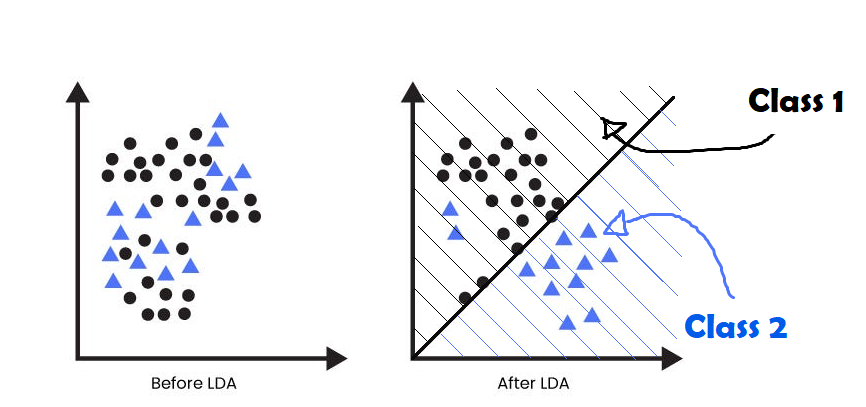

Where you can see that the data is hard to separate before LDA, and after LDA, the points are on a better set of axes to be classified (classification threshold indicated by the black line).

**2.4.2 LDA in MATLAB**

Now, we can train an LDA model using the `fitcdiscr()` function, and passing the data and labels.

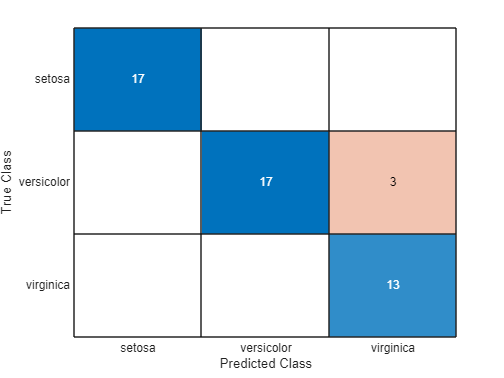

% Train the LDA model
ldaModel = fitcdiscr(X_train, y_train);

% Predict labels using the trained model
predicted_labels = predict(ldaModel, X_test);

% Visualize the confusion matrix

% The confusion matrix allows to see the true label of a sample, and the
% way it was classified. Boxes on the diagonal line of the confusion matrix
% means the sample was correctly classified. The number in each box
% represents the number of samples, if a box empty, this is 0.
confusionchart(y_test, predicted_labels);

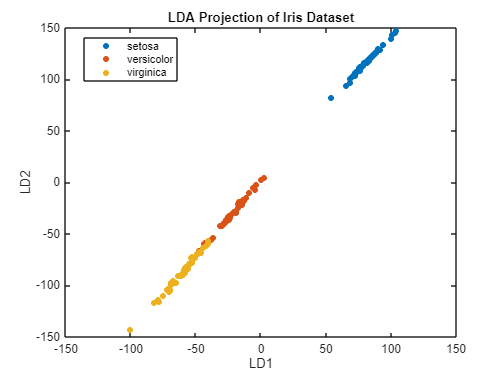

% Project data onto the discriminants (think about it as the PCA projection vectors)
LD1 = X_std * ldaModel.Coeffs(1,2).Linear; % Discriminant 1
LD2 = X_std * ldaModel.Coeffs(1,3).Linear; % Discriminant 2
%NOTE: Here we have 2 discriminants because we have 3 classes. We always
%have C-1 discriminants where C is the number of classes.
X_lda = [LD1, LD2]; % Combine into two dimensions
% Visualize the projected data in the LDA space
gscatter(X_lda(:,1), X_lda(:,2), y);
xlabel('LD1'); ylabel('LD2');
title('LDA Projection of Iris Dataset');

This plot gives us an insightful view of the LDA's projection.

*Exercise 2.3*

Look at the confusion matrix above. Can you say something about the missclassified samples using the LDA projection plot?

(Note: If you got 100% accuracy, it means you got a lucky train/test split, try running it again until you see some missclassified samples in the confusion matrix above)

*SOLUTION*:

We can see in the projection, that the setosa class has a very distinct discrimination with respect to the veriscolor and virginica classes, which is why we don't see any missclassified setosa samples. However, the versicolor and virginica classes have some overlap, which is where the missclassified samples come from.

# 3. Evaluation

### 3.1 Accuracy

Multiple ways to evaluate a model's performance exist. And these depend on what we want to evaluate the performance on. The most common evaluation metric is **accuracy**. This is an intuitive metric which tells you the proportion of correctly classified samples. It is therefore written as:

*Acc = n_correct / n_total *

And is most comonly expressed as a percentage.

However, accuracy has multiple flaws. First, if the data is unbalanced (meaning there are more samples from one class than another), accuracy might seem really good but our model is not generalising. Imagine you have 990 MRI scans of healthy controls, and 10 MRI scans of Parkinson patients. If your model doesn't learn and guesses "Healthy Control" all the time, it will achieve an accuracy of *Acc = 990/1000 = 99%.* 

Another way in which accuracy is flawed is that it doesn't take into account the number of classes. If we are trying to classify a binary problem (meaning it has two labels), the accuracy of a random predictor (also known as chance-level accuracy) will be of 50%. This means that an accuracy of around 60% is quite low. However, if we are classifying a sample into 1000 possible labels, an accuracy of 60% is much more impressive.

*Exercise 3.1*

Calculate (with code) the accuracy of the previously trained LDA model

(*Hint: You can use the *`strcmp() `*function, which compares whether two cells of strings are equal or not and returns the element-wise comparison array).*

disp(sum(strcmp(y_test,predicted_labels))/length(y_test)*100+"%")

94%


### 3.2 Confusion matrix and its metrics

We have seen a confusion matrix before, but let's dive deeper into it.

First, we can add some noisy samples to the data to lower our accuracy (this is more similar to what most confusion matrices with medical data will look like)

% Feel free to read this code if you are interested, but is not necessary
% that you understand it in detail
my_mu = mean(X,1);
my_std = std(X,1);
N = 100;
new_samples = zeros(N,4);
for i=1:4
    new_samples(:,i) = my_std(i)*randn(N,1)+my_mu(i);
end
X_aug = [X; new_samples];
y_aug = y;
for i=length(y):length(y)+N
    y_aug{i} = char(randsample(["setosa","versicolor","virginica"],1));
end

Let's fit the LDA model again on this data, and plot the confusion matrix:

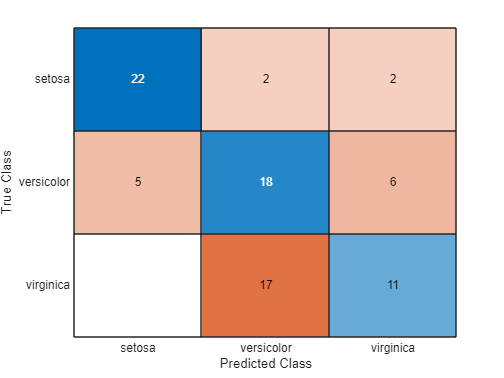

% Here we will use the lda_fit() function that is given to you in the Functions folder to not repeat all the steps again.
addpath Functions
[ldaModel_aug, predicted_labels_aug, X_train_aug, y_train_aug, X_test_aug, y_test_aug] = lda_fit(X_aug,y_aug);
confusionchart(y_test_aug, predicted_labels_aug); % Plot the confusion matrix.

*Exercise 3.2*

Calculate the accuracy of the new confusion matrix, given the number of classes, would you consider this a good model?

disp(sum(strcmp(y_test_aug,predicted_labels_aug))/length(y_test_aug)*100+"%")

61.4458%


With confusion matrices, you have a much better idea of your model's performance than with just accuracy. This is because we can see how each sample was missclassified.

With this, we can define new metrics for each class which are:

*True Positives (TP)*

Samples that were **predicted **as **class x** and **are** from class x

*True Negatives (TN)*

Samples that were **predicted** as **not class x** and **are not** from class x

 *False Positives (FP)*

Samples that were **predicted** as** class x** and **are not **from class x

*False Negatives (FN)*

Samples that were **predicted** as** not class x** and **are** class x

It gets a bit tricky to predict this in a multiclass setting, so we will do the same analysis but with just two classes:

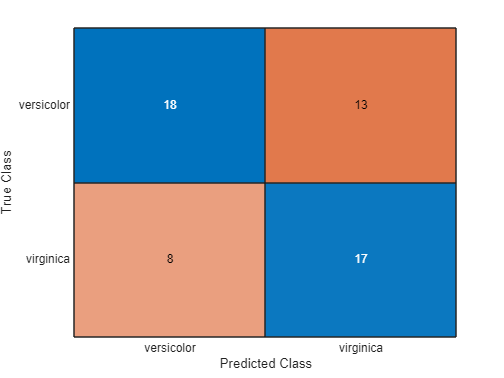

% Here we will use the lda_fit() function that is given to you in the Functions folder to not repeat all the steps again.
addpath Functions
X_aug = X_aug(~(y_aug=="setosa"));
y_aug = y_aug(~(y_aug=="setosa"));
[ldaModel_aug, predicted_labels_aug, X_train_aug, y_train_aug, X_test_aug, y_test_aug] = lda_fit(X_aug,y_aug);
confusionchart(y_test_aug, predicted_labels_aug); % Plot the confusion matrix.

*Exercise 3.3*

Given that your confusion matrix in array form is:

my_confmat = confusionmat(y_test_aug, predicted_labels_aug,'Order',gca().ClassLabels)

my_confmat =     18    13
     8    17


Calculate these metrics for your predictions (given that *"positive"* *= "versicolor"* and *"negative" = "virginica")*

tp = my_confmat(1,1)
tn = my_confmat(2,2)
fp = my_confmat(1,2)
fn = my_confmat(2,1)

fn = 8

You can verify them using this line of code:

addpath Functions
conf_metrics(my_confmat,1)

True Positives (TP) = 18
True Negatives (TN) = 17
False Positives (FP) = 13
False Negatives (FN) = 8


With this, we can calculate more metrics (like accuracy, they vary from 0 to 1):

*Recall or True Positive Rate (TPR) or Sensitivity:*

This metric gives us an idea of how good our model is at detecting a positive, in other words, how sensitive is our model to detecting positive samples.

*Precision:*

This metric gives us another idea of how good our model is at discerning positives. Instead of how sensitive we are to detecting positive samples, this can be seen as how accurate our model is in its positive predictions.

*Specificity or True Negative Rate (TNR):*

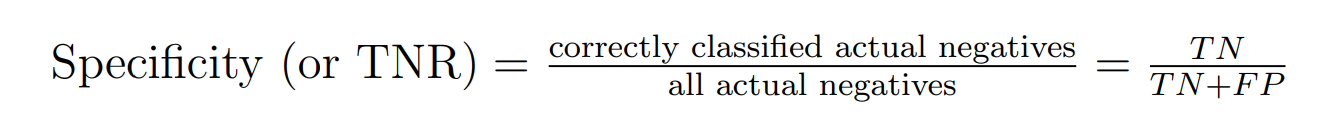

This metric gives us an idea of how good our model is at detecting negatives, this is the equivalent of Recall but for negative labels.

*Exercise 3.4*

Calculate these 3 metrics for your confusion matrix. Think about what this tells you of your LDA model.

recall = tp/(tp+fn)

recall = 0.6923

precision = tp/(tp+fp)

precision = 0.5806

specificity = tn/(tn+fp)

specificity = 0.5667

You can check your results with the following line:

addpath Functions
conf_metrics(my_confmat,1)

True Positives (TP) = 18
True Negatives (TN) = 17
False Positives (FP) = 13
False Negatives (FN) = 8


# 4. Challenge